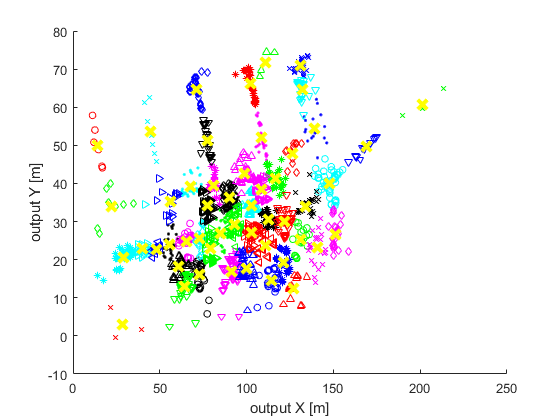


filename = '.\data\all_0_floor_out.csv';
%filename = 'C:\Users\USER\Documents\MATLAB\UJI_all_crd.csv';

delimiter = ',';

%% 각 텍스트 라인의 형식:
%   열1: double (%f)
%	열2: double (%f)
%   열3: double (%f)
% 자세한 내용은 도움말 문서에서 TEXTSCAN을 참조하십시오.
formatSpec = '%f%f%[^\n\r]';
%formatSpec = '%f%f';

%% 텍스트 파일을 엽니다.
fileID = fopen(filename,'r');

%% 형식에 따라 데이터 열을 읽습니다.
% 이 호출은 이 코드를 생성하는 데 사용되는 파일의 구조체를 기반으로 합니다. 다른 파일에 대한 오류가 발생하는 경우 가져오기 툴에서
% 코드를 다시 생성하십시오.
dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string',  'ReturnOnError', false);

%% 텍스트 파일을 닫습니다.
fclose(fileID);

%% 가져올 수 없는 데이터에 대한 사후 처리 중입니다.
% 가져오기 과정에서 가져올 수 없는 데이터에 규칙이 적용되지 않았으므로 사후 처리 코드가 포함되지 않았습니다. 가져올 수 없는
% 데이터에 사용할 코드를 생성하려면 파일에서 가져올 수 없는 셀을 선택하고 스크립트를 다시 생성하십시오.

%% 출력 변수 만들기
Trainingcoordinates21Aug17 = table(dataArray{1:end-1}, 'VariableNames', {'VarName1','VarName2'});

%% 임시 변수 지우기
clearvars filename delimiter formatSpec fileID dataArray ans;

X = Trainingcoordinates21Aug17{:,1:2};

colors = ['r','g','b','k','m','c'];
markers = ['.','o','*','d','x','v','^','>','<'];
colors_size = 6;
markers_size = 9;
cluster_num = 50;


[idx,C, sumd, D] = kmeans(X, cluster_num, 'Distance','sqeuclidean','Replicates',1000);
figure;
hold on
for i = 0:1:cluster_num
    color = colors( mod(i,colors_size)+1);
    marker = markers( mod(fix(i/colors_size),markers_size)+1 );
    plot(X(idx==i,1),X(idx==i,2),[color marker],'MarkerSize',5);
end

plot(C(:,1),C(:,2),'yx','MarkerSize',10,'LineWidth',3);
xlabel 'output X [m]';
ylabel 'output Y [m]';
hold off